### Question 3 - Plots

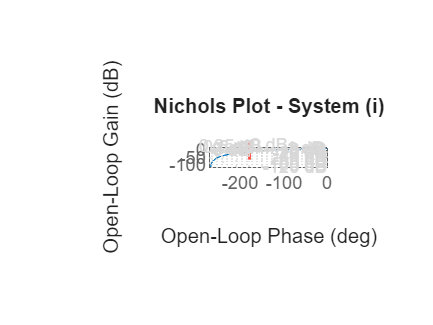

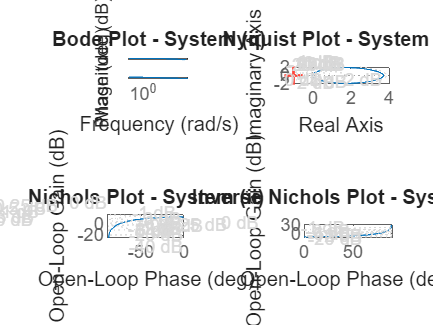

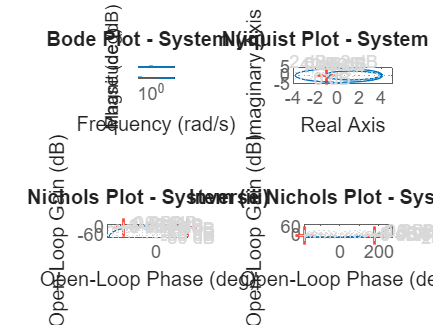

clear; clc; close all;

% Define transfer functions
s = tf('s');

% System i
G1 = 582.9 / (s^3 + 18*s^2 + 95*s + 126);

% System ii
G2 = (39.27*s^2 + 392.7*s + 1335) / (s^3 + 20*s^2 + 141*s + 360);

% System iii
G3 = (229.6*s - 229.6) / (s^4 + 11*s^3 + 46*s^2 + 86*s + 60);

% Store in array for looping
systems = {G1, G2, G3};
titles = {'System (i)', 'System (ii)', 'System (iii)'};

for k = 1:3
    figure;
    
    % --- Bode plot ---
    subplot(2,2,1);
    bode(systems{k});
    grid on; grid minor;
    title(['Bode Plot - ' titles{k}]);

    % --- Nyquist plot ---
    subplot(2,2,2);
    nyquist(systems{k});
    grid on;
    title(['Nyquist Plot - ' titles{k}]);

    % --- Nichols plot ---
    subplot(2,2,3);
    nichols(systems{k});
    grid on;
    title(['Nichols Plot - ' titles{k}]);

    % --- Inverse Nichols plot ---
    subplot(2,2,4);
    nichols(1/systems{k}); % Plot 1/G(jw) - not possible to flip M circles
    grid on;
    title(['Inverse Nichols Plot - ' titles{k}]);
end